## Sistema Ball & Beam

clear all;
close all;

### Constantes

Tempo de amostragem

Ts = 20e-3; %s

### Modelo do sistema

A = [-1.283 1;
     -0.329 0];
B = [0.03117 0.02721]';
C = [1 0];
D = [0];
sysD = ss(A, B, C, D, 'Ts', Ts)

sysD =
 
  A = 
           x1      x2
   x1  -1.283       1
   x2  -0.329       0
 
  B = 
            u1
   x1  0.03117
   x2  0.02721
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.02 seconds
Discrete-time state-space model.



### Projeto do controlador Hinf

Acell{1} = sysD.A;
Bcell{1} = sysD.B;
Bw{1} = [0 1]';
Du = [0]';
Dw = [0]';

saturacao = 1023; % pwm

[K,hinf,P] = hinf_discrete_sat_V2(Acell, Bcell, sysD.C, sysD.D, Dw, Bw, 1023);

MOSEK Version 10.1.22 (Build date: 2024-1-21 21:42:40)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 9               
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2 (scalarized: 34)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  

Ganhos do controlador

disp(K);

   32.7201  -30.7111



Autovalores da matriz P

disp(eig(P))

    0.6069
    3.0392



Norma $H_{\infty }$

disp(hinf)

    2.5689



### Amostragens

N = 100;

### Simulação

A = sysD.A;
B = sysD.B;
C = sysD.C;
D = sysD.D;

#### Condições iniciais

x_real{1} = [600 0]';
% x_ruido{1} = x_real{1} + U * w(:,1);

Estimadas

x_priori{1} = [0 0]';
x_hat{1} = [0 0]';
y_hat(1) = C * x_hat{1};
P_hat{1} = diag([0 0]);

Simulação do sistema discreto

for k = 1:N
    
    u(k) = K * x_real{k};

    % Saturar entrada

    if u(k) >= saturacao
        u(k) = saturacao;
    end

    if u(k) <= saturacao
        u(k) = -saturacao;
    end

    % Sistema real  
    x_real{k+1} = A * x_real{k} + B * u(k);
    y_real(k+1) = C * x_real{k+1};
    y_dot(k+1) = [0 1] * x_real{k+1};

%     % Sistema com ruído
%     x_ruido{k+1} = A * x_real{k} + B * u(k) + U * w(:,k);
%     y_ruido(k+1) = C * x_real{k+1} + v(:, k);
%     y_dot_ruido(k+1) = [0 1] * x_real{k+1} + v(:,k);

end

### Gráficos

#### Esfera

k = 1:N+1;

figure
hold on
% subplot(2,1,1)
stairs(k*Ts, y_real, 'b');
% stairs(k*Ts, y_ruido*10^2,'k:');
ylabel("Posição (cm)")
legend("Posição real", "Posição estimada", "Posição com ruído");

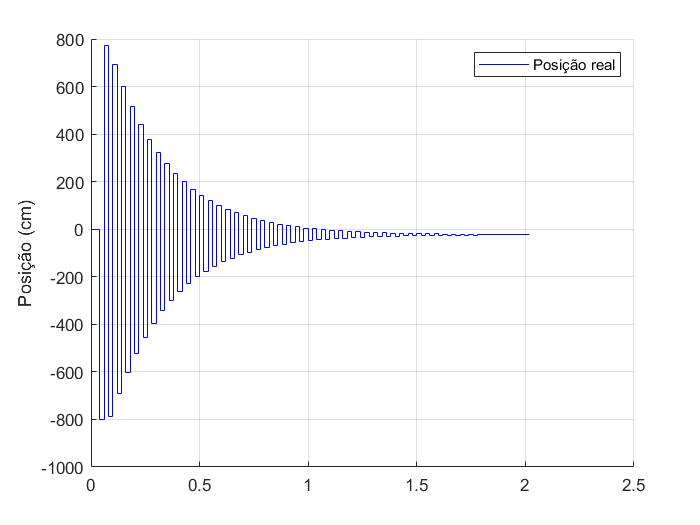

grid on
hold off


figure
hold on
stairs(k*Ts, y_dot, 'b');
grid on
legend("Velocidade real", "Velocidade com ruído", "Velocidade estimada");

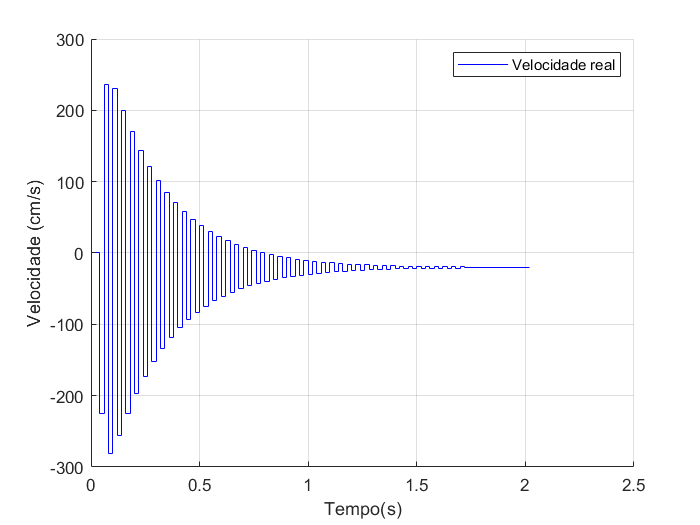

ylabel("Velocidade (cm/s)");
xlabel("Tempo(s)");
hold off

#### Sinal de controle

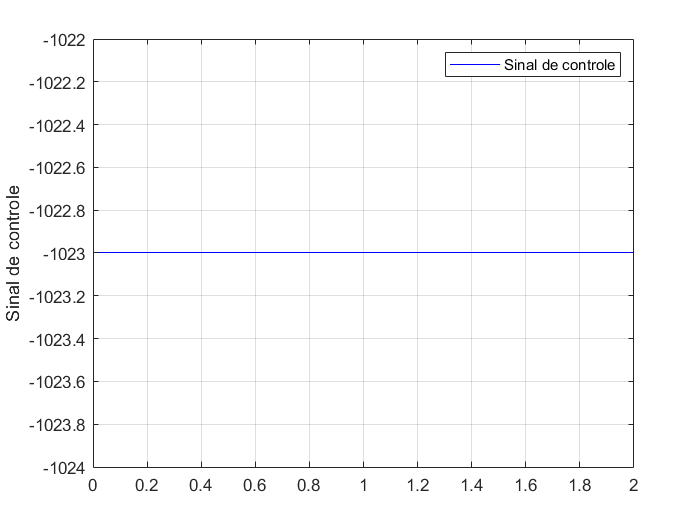

k = 1:N;

figure
stairs(k*Ts, u, 'b');
ylabel("Sinal de controle")
legend("Sinal de controle");
grid on